### Ejemplo audiovisual:

Creación del sistema de inferencia borrosa:

% Creación del sistema de inferencia borrosa:
fis = mamfis('Name',"audiovisual");

Variables input:

% Variables input del sistema:
fis = addInput(fis,[0 5500],'Name',"frecuencia");
fis = addInput(fis,[50 100],'Name',"intensidad");

Funciones de pertenencia:

% Funciones de pertenencia relacionadas con el primer input:
fis = addMF(fis,"frecuencia","trimf",[-200 0 200],'Name',"muy_baja");
fis = addMF(fis,"frecuencia","trimf",[0 200 400],'Name',"baja");
fis = addMF(fis,"frecuencia","trimf",[100 500 1100],'Name',"media");
fis = addMF(fis,"frecuencia","trimf",[200 1300 3400],'Name',"alta");
fis = addMF(fis,"frecuencia","trapmf",[1500 3600 6000 6000],'Name',"muy_alta");

% Funciones de pertenencia relacionadas con el segundo input:
fis = addMF(fis,"intensidad","trapmf",[45 50 70 75],'Name',"muy_baja");
fis = addMF(fis,"intensidad","trimf",[65 80 85],'Name',"baja");
fis = addMF(fis,"intensidad","trimf",[80 85 90],'Name',"media");
fis = addMF(fis,"intensidad","trimf",[85 90 100],'Name',"alta");
fis = addMF(fis,"intensidad","trimf",[90 105 120],'Name',"muy_alta");

Añadimos la variable output del sistema:

fis = addOutput(fis,[0 1],'Name',"tamaño");

Con sus funciones de pertenencia:

fis = addMF(fis,"tamaño","trimf",[-0.5 0 0.5],'Name',"pequeño");
fis = addMF(fis,"tamaño","trimf",[0 0.5 1],'Name',"mediano");
fis = addMF(fis,"tamaño","trimf",[0.5 1 1.5],'Name',"grande");

Asignación de las reglas de lógica borrosa:

- IF (**frecuencia** is **muy_baja**) AND (**intensidad** is **alta**), THEN (**tamaño** is **grande**)

- IF (**frecuencia** is **baja**) AND (**intensidad** is **muy_alta**), THEN (**tamaño** is **grande**)

- IF (**frecuencia** is **media**) OR (**intensidad** is **media**), THEN (**tamaño** is **mediano**)

- IF (**frecuencia** is **muy_alta**) AND (**intensidad** is **muy_baja**), THEN (**tamaño** is **pequeño**)

- IF (**frecuencia** is **muy_alta**) AND (**intensidad** is **baja**), THEN (**tamaño** is **pequeño**)

ruleList = [1 4 3 1 1;
            2 5 3 1 1;
            3 3 2 1 2;
            5 1 1 1 1;
            5 2 1 1 1];

Añadimos las normas creadas al sistema de inferencia borroso:

fis = addRule(fis,ruleList);

Accedemos a las propiedades del sistema:

1- Inputs:

fis.Inputs

ans =   1×2 fisvar array with properties:

    Name
    Range
    MembershipFunctions

  Details:
             Name          Range       MembershipFunctions
         ____________    __________    ___________________

    1    "frecuencia"     0    5500        {1×5 fismf}    
    2    "intensidad"    50     100        {1×5 fismf}    


2- Funciones de pertenencia:

fis.Inputs(1).MembershipFunctions

ans =   1×5 fismf array with properties:

    Type
    Parameters
    Name

  Details:
            Name         Type            Parameters       
         __________    ________    _______________________

    1    "muy_baja"    "trimf"     {[         -200 0 200]}
    2    "baja"        "trimf"     {[          0 200 400]}
    3    "media"       "trimf"     {[       100 500 1100]}
    4    "alta"        "trimf"     {[      200 1300 3400]}
    5    "muy_alta"    "trapmf"    {[1500 3600 6000 6000]}


3- Gráfico general:

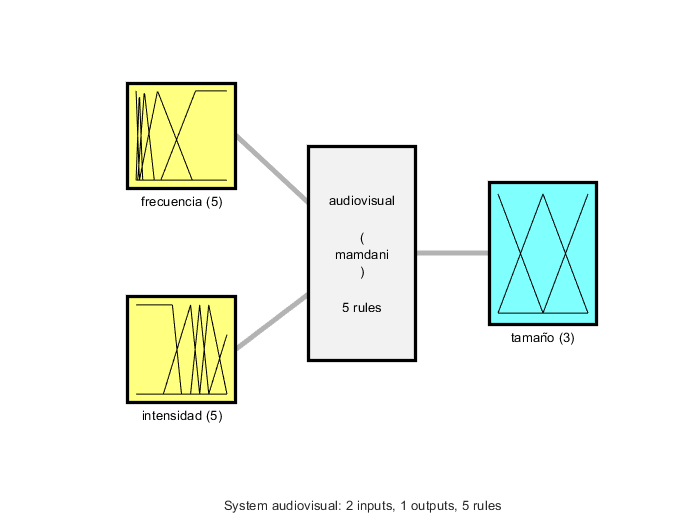

plotfis(fis)

4- Gráfico con las funciones de pertenencia de la primera variable input:

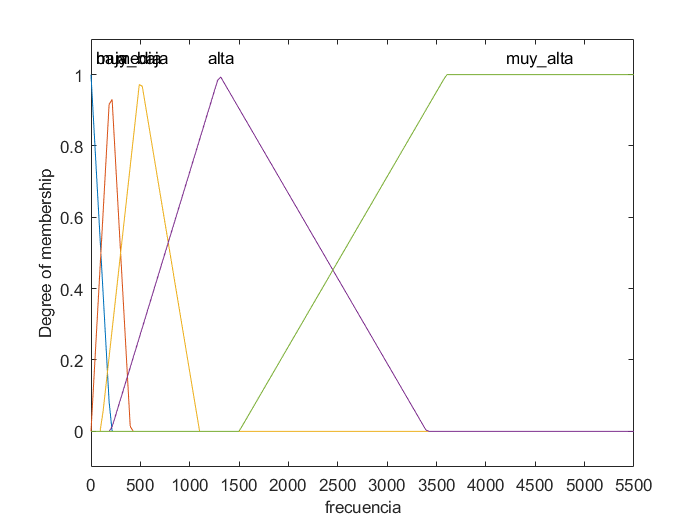

plotmf(fis,'input',1)

5- Gráfico con las funciones de pertenencia de la segunda variable input:

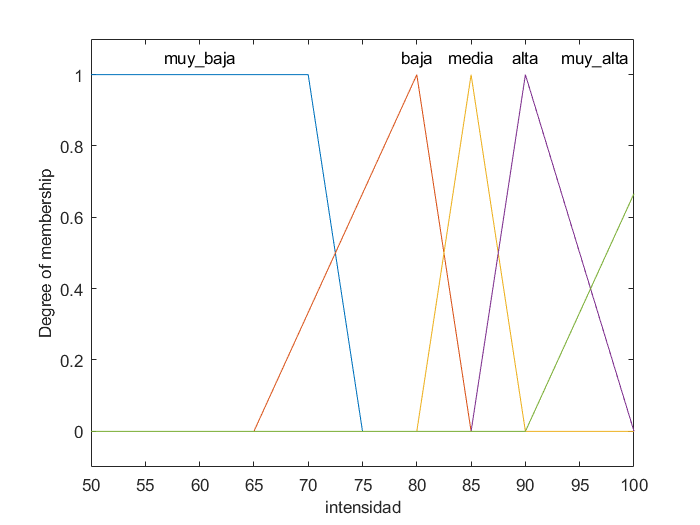

plotmf(fis,'input',2)

6- Gráfico con las funciones de pertenencia de la variable output:

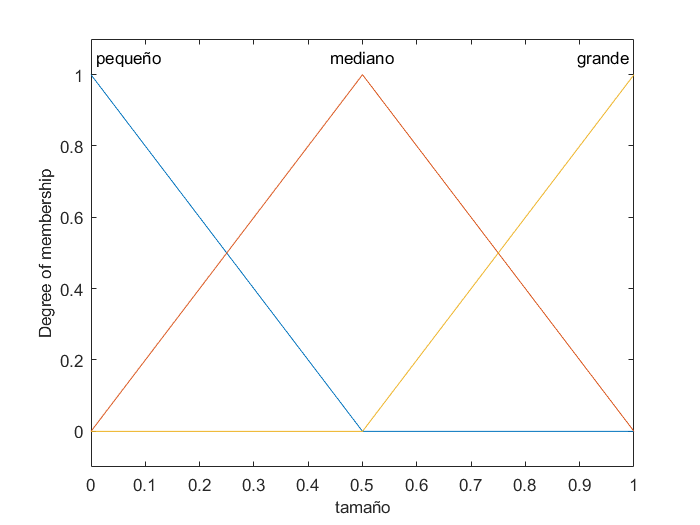

plotmf(fis,'output',1)

7- Reglas del sistema:

fis.Rules

ans =   1×5 fisrule array with properties:

    Description
    Antecedent
    Consequent
    Weight
    Connection

  Details:
                                     Description                            
         ___________________________________________________________________

    1    "frecuencia==muy_baja & intensidad==alta => tamaño=grande (1)"     
    2    "frecuencia==baja & intensidad==muy_alta => tamaño=grande (1)"     
    3    "frecuencia==media | intensidad==media => tamaño=mediano (1)"      
    4    "frecuencia==muy_alta & intensidad==muy_baja => tamaño=pequeño (1)"
    5    "frecuencia==muy_alta & intensidad==baja => tamaño=pequeño (1)"    


8- Superficie de la variable output en función de los diferentes input:

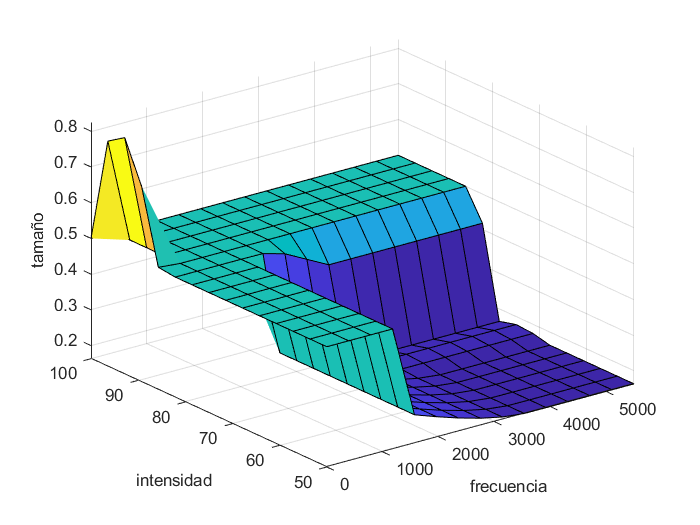

gensurf(fis)

Evaluación del sistema de inferencia borroso creado con múltiples inputs:

evalfis(fis,[100, 90])

ans = 0.8082

evalfis(fis,[2000, 55])

ans = 0.2190